Ts_roll = 1/50;
% Plant
A_roll = [-1/t_S, 0; r_S/I_x(1), 0];
b_roll = [1/t_S; 0];
c_roll = [0,1];
d_roll = 0;

sysC = ss(A_roll,b_roll,c_roll,d_roll);
sysD_roll = c2d(sysC,Ts_roll,'zoh');

    
% Requirments
zeta = 0.707;
ts2 = 1;

% Poles
wn = 4/(zeta*ts2)

wn = 5.6577

p_s = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
     -zeta*wn - 1i*wn*sqrt(1-zeta^2)];
p_z = exp(p_s*Ts_roll);

[C_roll,info] = pidtune(sysD_roll,'PI')

C_roll =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 11.8, Ki = 7.49, Ts = 0.02
 
Sample time: 0.02 seconds
Discrete-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 2.7590
           PhaseMargin: 60.0000


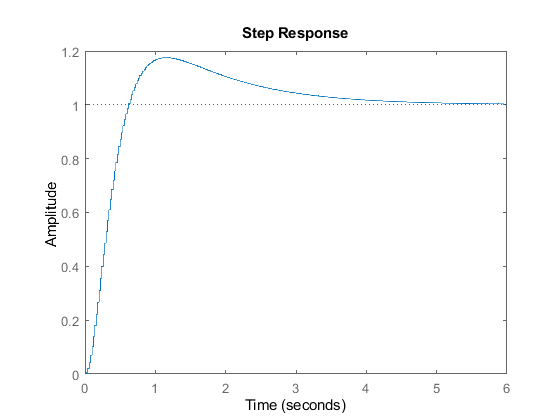

step(feedback(C_roll*sysD_roll,1))